clc;
clear all;
close all;
global is_increasing function_used
is_increasing = 0 %initial conditions

is_increasing = 0

function_used = 0 %initial function

function_used = 0


global v on_what count targets_x targets_y;
v = 1;
on_what = 1;
time = [0, 50];
r_min = 2;
r_max = 3;
targets_x = [-r_min, r_min];
targets_y = [r_min, r_min];
K =-15;
r_range = linspace(r_min, r_max, 100);
max_range = linspace(0, r_max);
a1 = -1;
b1 = 10;
tend = time(end)

tend = 50

count = 0;

%m = v * (r_max+r_min) / (r_max-r_min);
%c = v*r_max - m*r_max;

syms a  b;
eqn1 = @(a,b)  a*(r_min)^2+b*r_min == +v*r_min-K;
eqn2 = @(a,b) a*(r_max)^2+b*r_max == -v*r_max-K;
sol = solve({eqn1, eqn2}, [a, b]);

global g f;
g = @(r) (sol.a).*r.^2+(sol.b).*r+K;
f = @(r) 2*(sol.a)+(sol.b)./r;



tol = 1e-5;
 
options = odeset('RelTol', tol, 'AbsTol', tol, 'Events', @time_to_switch);
traj = @odefunc;


t1 = time(1);
Y = [-r_max-r_min,r_min,pi/2];
while(t1(end)< time(end))
    [ts1, Ys1] = ode45(traj, [t1(end),tend], double(Y(end,:)), options);
    t1 = cat(1,t1,ts1(2:end));
    Y = cat(1,Y,Ys1(2:end,:));
    prev_target=1
    r_switch = sqrt((Y(1)-targets_x(2))^2+(Y(2)-targets_y(2))^2);
    if(t1(end)==tend)
        break
    end
    Y(end,3)=Y(end,3)+2*asin(r_min/r_switch);
    [ts2, Ys2] = ode45(@(t,Y) odefunc1(t,Y), [t1(end),tend], double(Y(end,:)), options);
    t1 = cat(1,t1,ts2(2:end));
    Y = cat(1,Y,Ys2(2:end,:));
    prev_target=2;



end

prev_target = 1

## Plotting

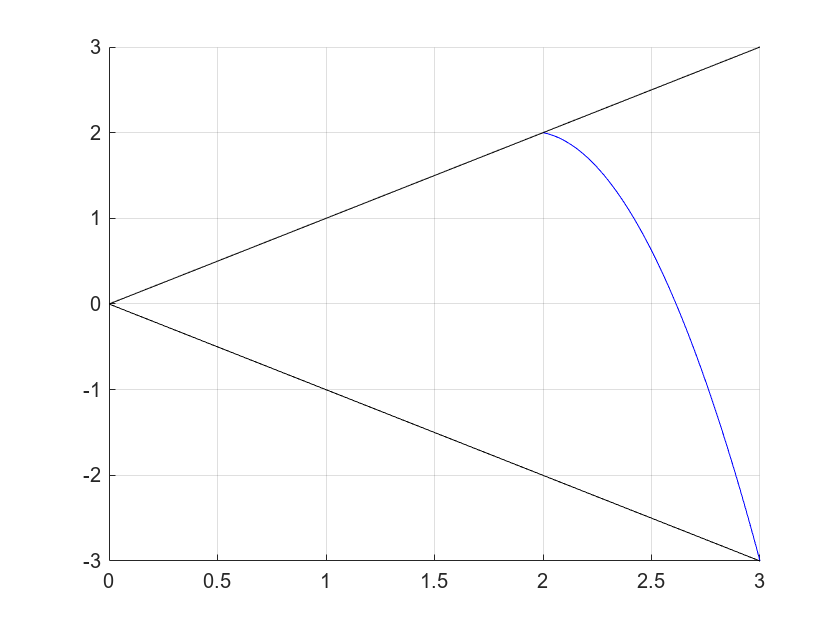

figure;
hold on
grid on;
plot(r_range, g(r_range), 'b');
plot(max_range, v*max_range, 'k');
plot(max_range, -v*max_range, 'k');
hold off

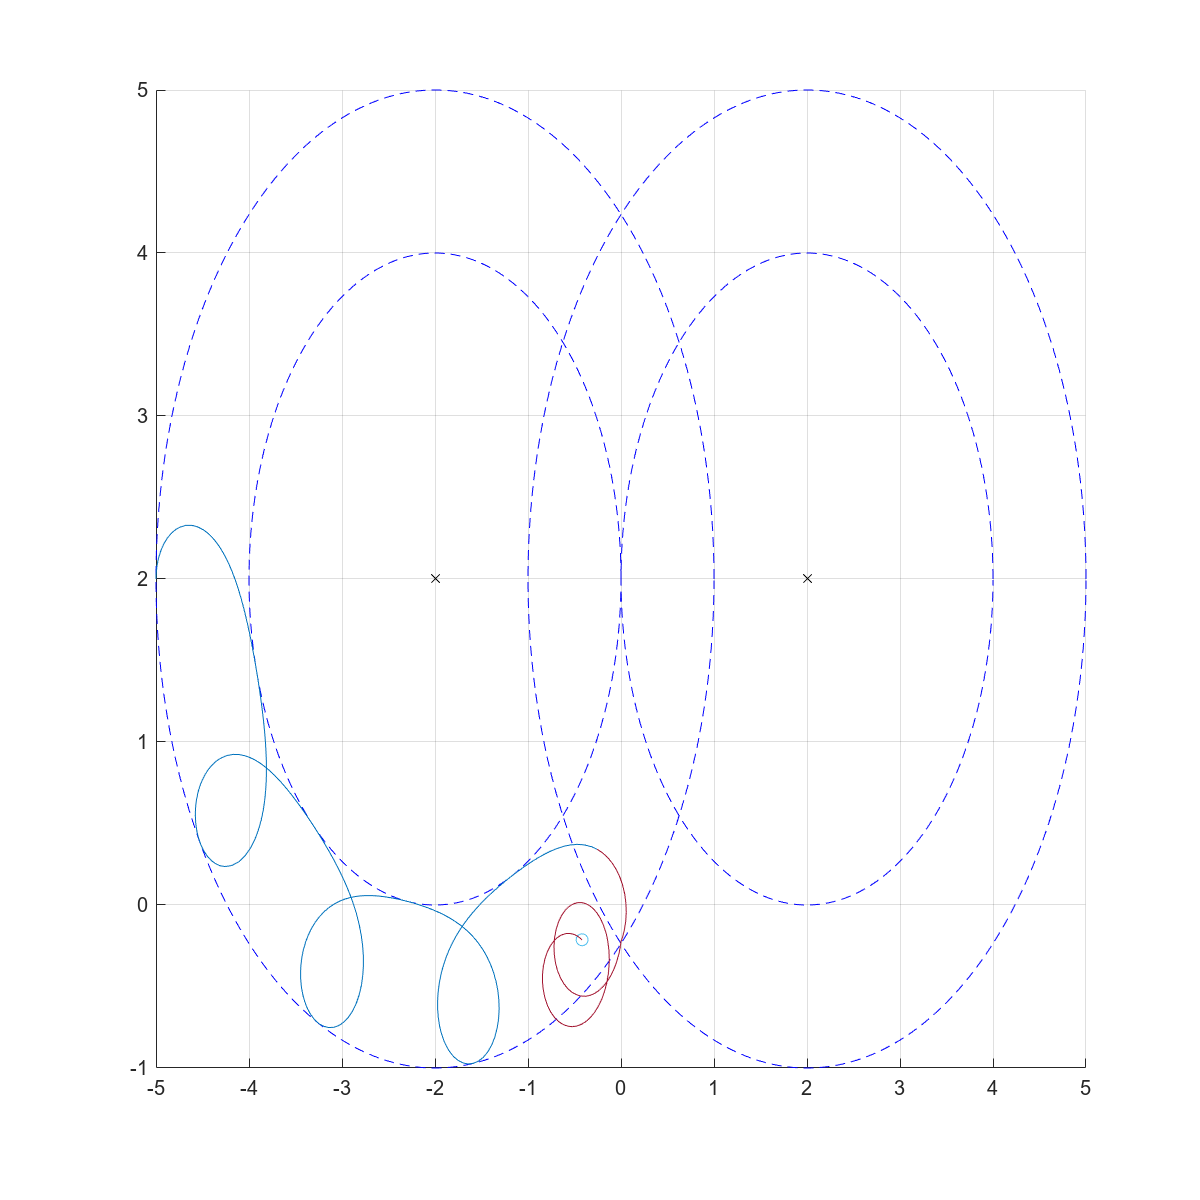


angle = 0:0.01:2*pi;
figure;
set(gcf, 'Position', [1000 100 800 800]);
grid on;
hold on
for i = 1:length(targets_x)
    plot(targets_x(i) + r_min*cos(angle), targets_y(i) + r_min*sin(angle), '--b');
    plot(targets_x(i) + r_max*cos(angle), targets_y(i) + r_max*sin(angle), '--b');
end
plot(targets_x, targets_y, 'xk')

    %     plot(Y1(:,1), Y1(:,2), 'b')
comet(Y(:,1), Y(:,2));




## Functions used

function [value,isterminal,direction] = time_to_switch(t1,Y1)
global r_switch targets_x targets_y
value = sqrt((Y1(1)-targets_x(1))^2+(Y1(2)-targets_y(1))^2)-sqrt((Y1(1)-targets_x(2))^2+(Y1(2)-targets_y(2))^2);
isterminal = 1;
direction = -1;
end

function ret = odefunc1(t, Y)
global f v count r_switch targets_x targets_y
x = Y(1);
y = Y(2);
alpha = Y(3);
r_ = sqrt((x-targets_x(2))^2 + (y-targets_x(1))^2);

% Unicycle dynamics
x_dot = v * cos(alpha);
y_dot = v * sin(alpha);
alpha_dot = f(r_);

% Return

ret = double([x_dot; y_dot; alpha_dot]);
end

function ret = odefunc(t, Y)
global f v r_switch count targets_x targets_y;

% Unpacking variables
x = Y(1);
y = Y(2);
alpha = Y(3);
r_ = sqrt((x-targets_x(1))^2 + (y-targets_y(1))^2);

% Unicycle dynamics
x_dot = v * cos(alpha);
y_dot = v * sin(alpha);
alpha_dot = f(r_);

% Return
ret = double([x_dot; y_dot; alpha_dot]);
end

